% load in files
% may vary on your computer
addpath ./data/
mars_path = "mars_transfer_ephem.txt";
earth_path = "earth_transfer_ephem.txt";

% some constants
m2au = 6.6845871226706e-12; % AU/m

R_m = 3389.5; % Mars volumetric mean radius (km)
alt = 500; %km
a = R_m + alt %km

a = 3.8895e+03

e = 0

e = 0

% use nodal regression to match mean motion of the sun (sun synchronicity)
J2 = 1955.5e-6; % Mars J2 (dimensionless)
mu_m = 4.282837e4 % km^3 s^-2

mu_m = 4.2828e+04

trop_yr = 686.973 * 24 * 60 * 60; % sec
n = sqrt(mu_m/a^3); % sec^-1
cosI = (2*pi/trop_yr)*(-2*a^2*(1-e^2)^2)/(3*n*R_m^2*J2);
I = acos(cosI)*180/pi;
%calculate approx velocity in mars orbit for delta v calculation
v_f = sqrt(mu_m/a) % km s^-1

v_f = 3.3183


% try to define argument of periapsis and longitude of asc. node through
% orbital transfer
tdep = datetime('19-May-2031');
tarr = datetime('24-Feb-2032');
dt = daysact(tdep,tarr);

% orbital elements of transfer
a_t = 1.2316; % AU
e_t = 0.1797;
E = 0.1103;
I_t = 0.0195;
w_t = 3.0063;
O_t = 1.0052;
tp_t = 492.0249; % days
mu_s = 1.32712440042e20*(m2au)^3*(86400)^2; % AU^3 day^-2

[t_t, X_t, Y_t, Z_t,vx,vy,vz,points] = kepler_2body_proj(a_t,e_t,mu_s,I_t, ...
    w_t,O_t,tp_t,dt);

vf = [vx(end); vy(end); vz(end)]*1731 % velocity of spaceship at end of transfer (km s^-1)

vf =   -21.8291
    6.3071
    0.4253


r =    -0.5446
   -0.8525
    0.0001


r =     1.1473
    0.8794
   -0.0097


r =     0.4980
    1.3450
    0.0059


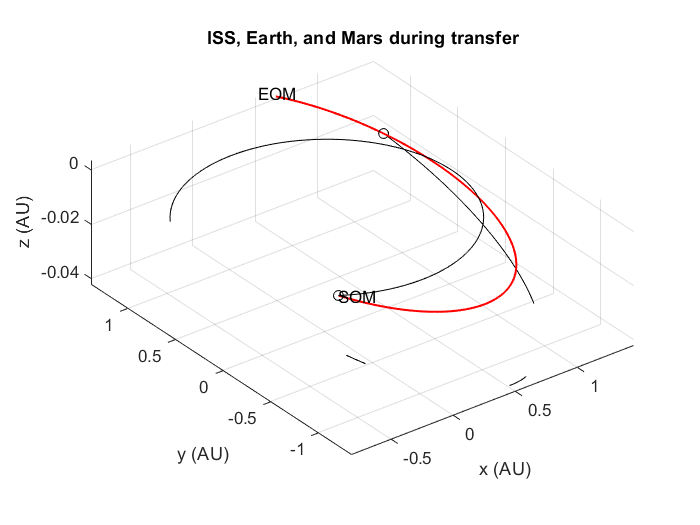

plotOrbit([mars_path,earth_path],{t_t,X_t,Y_t,Z_t,vx,vy,vz}, false, points)

% v_circ = [sqrt(mu_m/a);0;0];
% % how to get CdAm? I used this: https://space.stackexchange.com/questions/9482/how-long-would-iss-stay-in-orbit-if-it-didnt-get-reboosts
% % or this: https://www.researchgate.net/publication/263970589_Theoretical_Model_of_Drag_Force_Impact_on_a_Model_International_Space_Station_Satellite_due_to_Solar_Activity
% Cd = 2.2; % typical for most spacecraft
% A = 130; % m^2
% m = 15e4; %kg
% CdAm = Cd*A/m;
% 
% h = sqrt(a*mu_m);
% r_m = peri2helio(0,I,0)*[a;0;0];
% v_m = peri2helio(0,I,0)*[0;mu_m/h;0];
% Tp = 2*pi*sqrt(a^3/mu_m);
% [t,r,~,te,~] = dragMarsOrbitInt(r_m,v_m,[0,10000*Tp],CdAm);

% hs = sqrt(sum(r.^2,2)) - R_m;
% plot(t./86400,hs);

% QinetiQ T6 thrusters (used on BepiColombo mission)
% their masses are 8.3 kg!! cool!!
mT6 = 8.3;
n_thrusters = 1;
Isp = 4324; %s
T = 150; %mN
P = 4628; %W

dv1 = 2.9992; %dv in LEO
dv2 = 6.1197; %dv in LMO
m0 = 150000; %kg
gLEO = 9.80665*0.9; %m/s^2
gMEO = 0.379*gLEO;

dm = @(dv,g,m0,n) (m0+mT6*n)*(1-exp(-dv/(n*Isp*g)));

dm1 = dm(dv1,gLEO,m0,1);
dmtot = dm1 + dm(dv2,gMEO,m0-dm1,1)

dmtot = 75.2384